# Forced Harmonic Oscillator with Metropolis MCMC

## Theory

In the path integral formulation, the propagator of a particle going from $x_i$ at time $t_i$ to $x_f$ at time $t_f$ is given by 


$$\langle x_f , t_f| x_i , t_i \rangle = \int Dx(t) e^{iS/\hbar}$$


where the action $S$ of the path $x(t)$ is 


$$S = \int_{t_i}^{t_f}dt \left[\frac{1}{2} m \left(\frac{dx}{dt}\right)^2 - V\left(x(t)\right)\right]$$


In the imaginary time path integral, time $t$ is replaced by $-i \tau$ where $\tau$ is real. In this formulation, the partition function


$$Z = \mathrm{Tr} \left(e^{-\hat{H}\left(\tau_f - \tau_i \right)/\hbar}\right)$$


comes out to be


$$Z = \int Dx(t) e^{-S/\hbar}$$


where $S$ is the Eucledian action over a path $x(\tau)$.


$$S = \int_{\tau_i}^{\tau_f}d\tau \left[\frac{1}{2} m \left(\frac{dx}{d\tau}\right)^2 + V\left(x(\tau)\right)\right]$$


The expression of action of the path $x(t)$ for the Forced Harmonic Oscillator is 


$$S =\int dt \left[\frac{1}{2}m\dot{x}(t)^2 - \frac{1}{2}kx(t)^2 + x(t)F(t)\right]$$


with 


$$V\left(x(t), t \right) = \frac{1}{2}kx(t)^2 - x(t)F(t)$$


So $V$ has an explicit dependence on time. 

## Computational Method

The Metropolis Hastings algorithm has been used on a discrete time lattice with $N$ time slices. The trajectory over this time lattice is characterized by the real number array $(x_1, \dots, x_N)$. The initial configuration $\text{path}^{(0)}$ is updated by the Metropolis algorithm to get the next configuration $\text{path}^{(1)}$ and so on. One update to $x_i$ for each time slice $i$ constitutes one "sweep". 

- The lattice sites are randomly visited. 

- A new value $x_i^{(\text{new})} = x_i + u$ is proposed from a normal distribution around the old value $x_i$. 

- The change in the action $\delta S$ due to this proposal is computed. 

- The probability of acceptance of this proposal is $\text{min}\left\{e^{-\delta S} , 1\right\}$.

This way, we always accept propositions that decrease the action. Propositions that increase the action are accepted with a probability $e^{-\delta S}$.

In the random walk Metropolis algorithm, the probability $P$ of proposing a state $b$ from the current state $a$ is 


$$P = \frac{\pi(b)}{\pi(a)}$$


where $\pi$ is the target probability distribution. The probability of accepting the proposition is $\text{min}\left\{P,\, 1\right\}$. In our case, $\pi$ is $e^{-S}$ where $S$ is the Euclidean action. 

To make the action dimensionless, we have taken 


$$\hbar = 1 = c$$


which implies


$$[\text{time}] = [\text{length}] = [\text{mass}^{-1}] = [\text{energy}^{-1}]$$


We have used dimensionless variables


$$\tilde{m} = m \delta \tau,\ \tilde{\omega} = \omega \delta \tau,\ \tilde{x}_i= \frac{x_i}{\delta \tau},\ \tilde{F}_i = F_i \left(\delta\tau\right)^2$$


where $\delta\tau$ is the lattice spacing. With this, the dimensionless action $\tilde{S}$ becomes 


$$\tilde{S} = \sum_{i = 1}^N\frac{1}{2}\tilde{m}\left(\tilde{x}_{i+1}-\tilde{x}_i\right)^2 + \frac{1}{2}\tilde{m}\tilde{\omega}^2\tilde{x}_i^2 - \tilde{x}_i \tilde{F}_i$$


The right hand side in terms of the dimensionful variables is $\displaystyle \sum_{i=1}^N \delta \tau \left[ \frac{1}{2}m\left(\frac{x_{i+1} - x_i }{\delta \tau}\right)^2 + \frac{1}{2}m\omega^2x_i^2 - x_i F_i \right]$. In the accept/reject step of the algorithm, we have used $\tilde{S}$ instead of $S$. 

## Script

The metropolis algorithm is implemented with the function `metropolis`. The forcing function is taken to be sinusoidal. 


$$F(t) = \lambda \sin (k\omega t)$$


We now set the values of the following parameters.

- $n \equiv$ number of sweeps (metropolis time)

- $N \equiv$ number of points in the discrete time lattice (time)

- $\lambda \equiv$ coupling constant of the time dependent term

- $k \equiv$ how many times the SHO frequency is the forcing frequency

clear
close all
clc

N = 120; %time lattice points
n = 10000; %number of sweeps (1000 for fast execution)
lambda = 3; %coupling constant
k = 0.6; %frequency multiplier

In order to create plots against time and metropolis time, we create the following arrays. 

time = 1:1:N;
sweeps = 1:1:n;

Now we generate the paths with the `metropolis` funtion. 

[patharr, S] = metropolis(n, N, lambda, k);

The probability density function is given by the histogram of all the paths generated. 

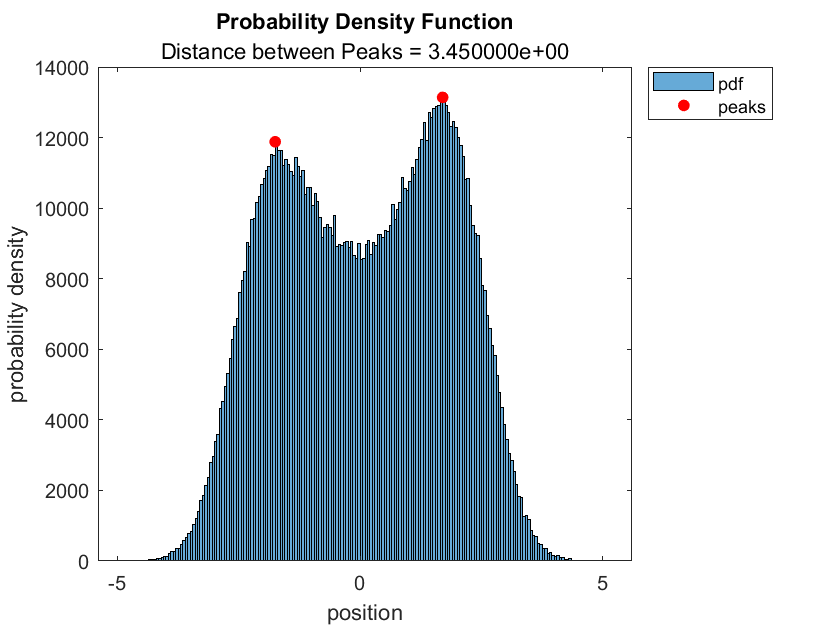

[counts, binedges] = histcounts(patharr);
[pks, indices] = findpeaks(counts, "NPeaks", 2, "MinPeakWidth", 6); %enter number of peaks from plot
pklocs = binedges(indices);

figure
histogram(patharr);
hold on;
plot(pklocs, pks, 'r.', 'MarkerSize', 20);
xlabel('position');
ylabel('probability density');
title('Probability Density Function');
legend('pdf', 'peaks', 'location', 'bestoutside');
subtitle(sprintf('Distance between Peaks = %d', abs(pklocs(1, 1) - pklocs(1, 2)))); %modify in case of multiple peaks

The following is a plot containing the initial path fed into the algorithm and the last path generated by it.

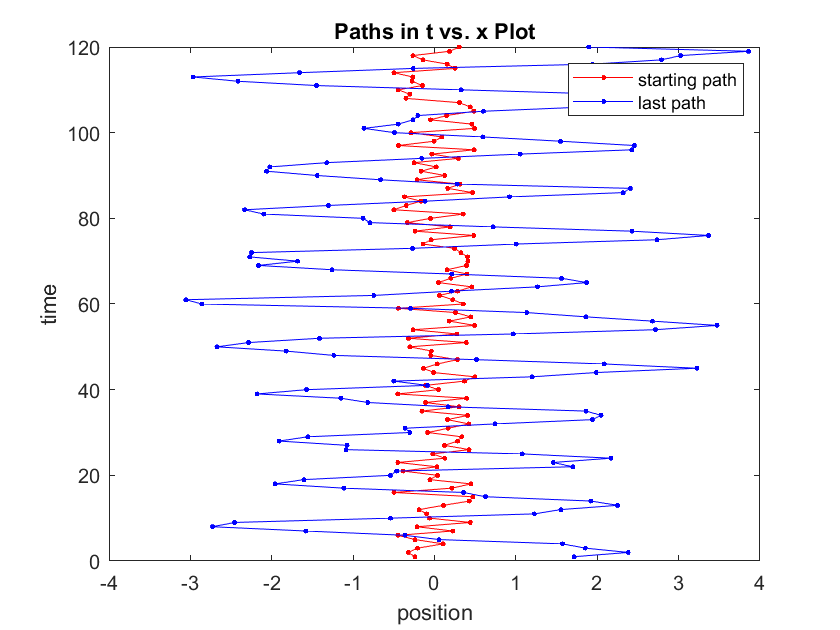

figure
plot(patharr(1, :), time, 'r.-', patharr(n+1, :), time, 'b.-');
legend('starting path', 'last path');
xlabel('position');
ylabel('time');
title('Paths in t vs. x Plot')

We can get the probability distribution at each time point and note the location of the peaks at those time points. This gives us the most probable location of the particle as a function of time. We can also plot the probability density of the particle to be near origin as a function of time. 

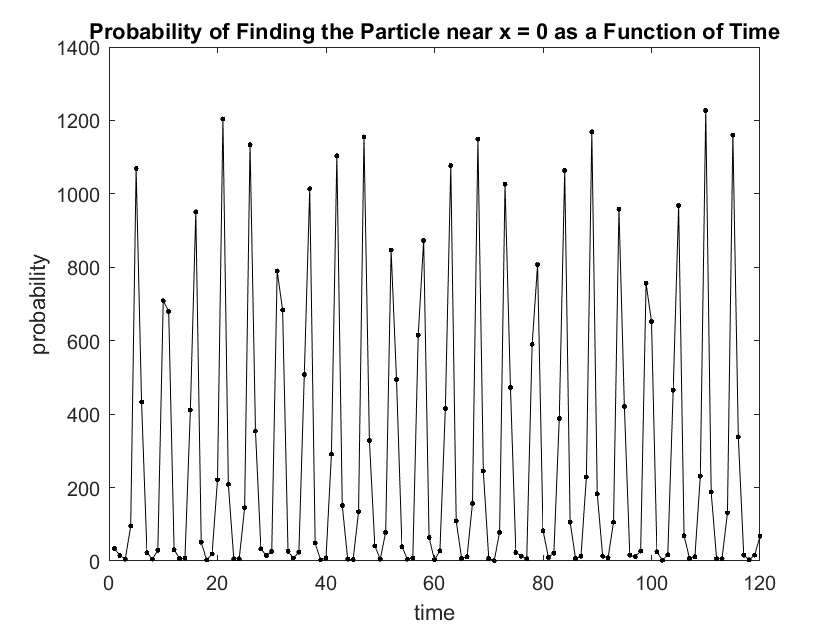

ret = []; %probability of returning near zero
edges = [-0.1 0.1]; %region around zero
pkpos = []; %position of the peak at every time point

for i = 1:N
    num = histcounts(patharr(:, i), edges);
    ret = [ret num];
    [bincount, binlocation] = histcounts(patharr(:, i));
    [pk, ind] = max(bincount);
    pkpos = [pkpos binlocation(ind)];
end

figure
plot(time, ret, 'k.-');
xlabel('time');
ylabel('probability');
title('Probability of Finding the Particle near x = 0 as a Function of Time');

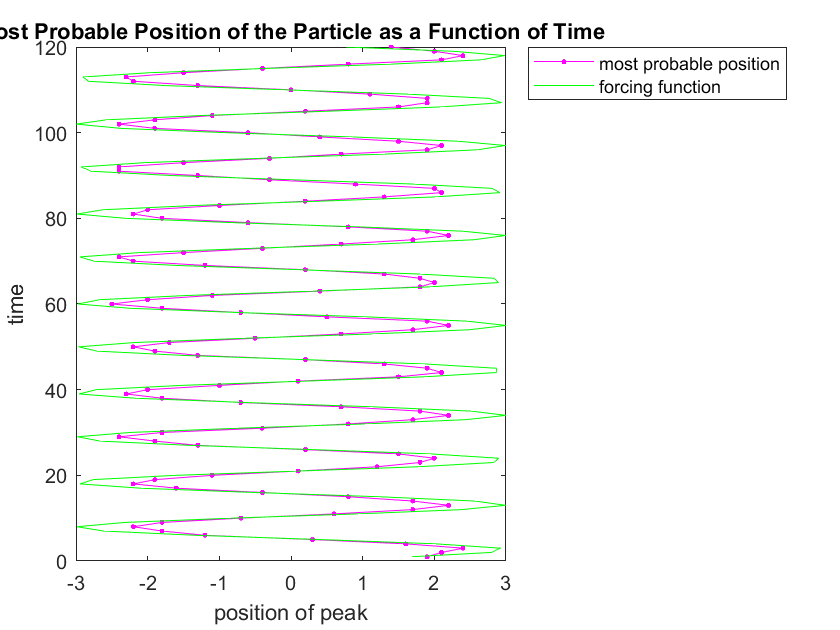

figure
plot(pkpos, time, 'm.-');
hold on;
plot(lambda*sin(k*time), time, 'g-', 'MarkerSize', 4);
xlabel('position of peak');
ylabel('time');
title('Most Probable Position of the Particle as a Function of Time');
legend('most probable position', 'forcing function', 'location', 'bestoutside');

To check for the number of metropolis sweeps required to reach the target distribution, we have plotted the thermalization of the action. 

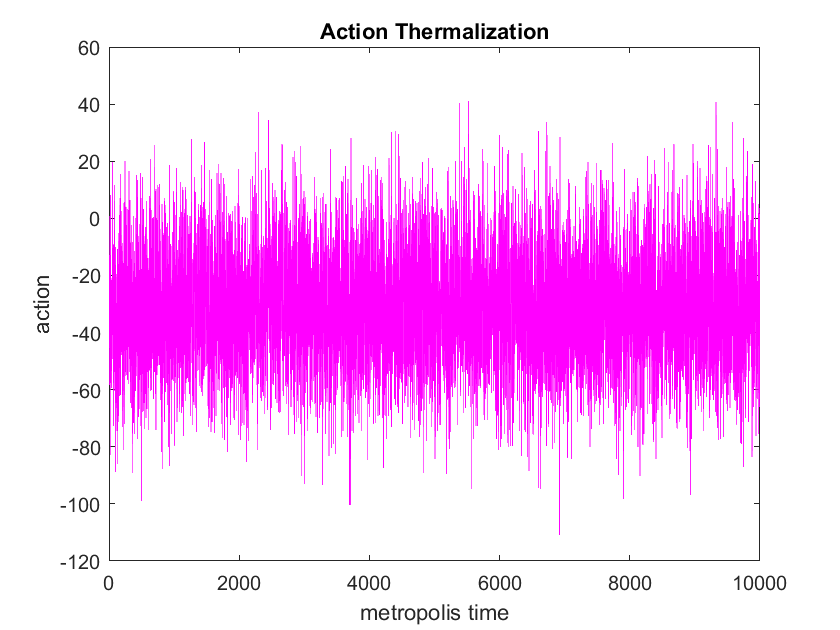

figure
plot(sweeps, S, 'm-');
xlabel('metropolis time');
ylabel('action');
title('Action Thermalization');

We see that the burn-in metropolis time is less than 100. 